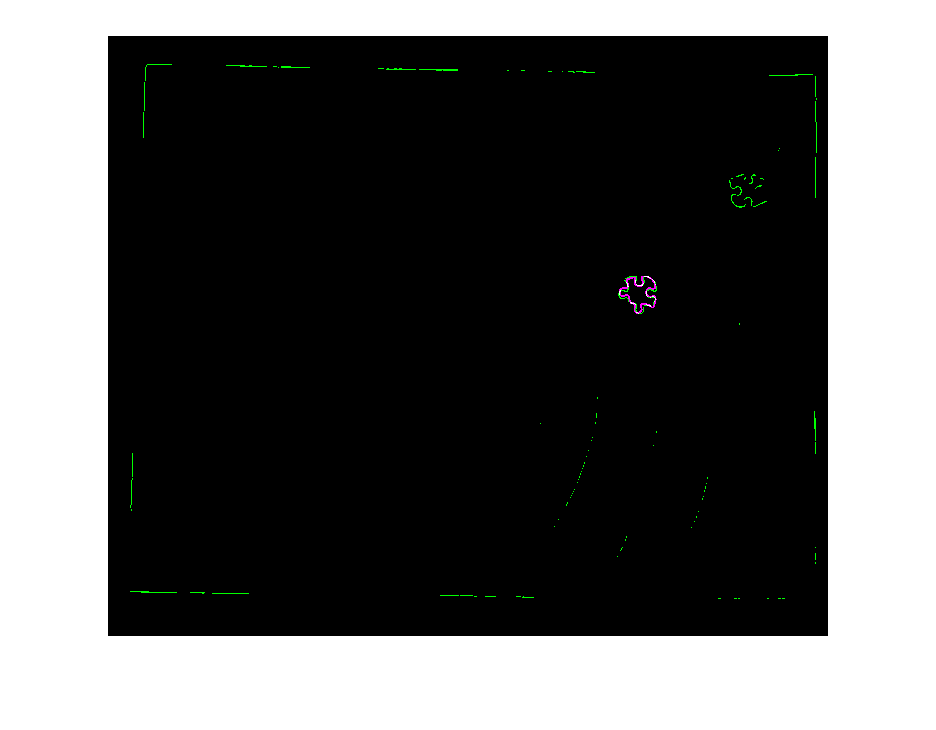

% Part 1 Hough Transform
img2 = double(imread('~/MatlabProjects/cs567Midterm/orange_piece.jpg'));
img1 = imread('~/MatlabProjects/cs567Midterm/main.jpg');
main=double(img1);
temp=double(img2);

% resize
main = imresize(main,0.2);
temp = imresize(temp,0.2);
main = main(:,:,1);
temp = temp(:,:,1);
ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';

gx = conv2(main, ksx, 'same');
gy = conv2(main, ksy, 'same');

gx2 = conv2(temp, ksx, 'same');
gy2 = conv2(temp, ksy, 'same');

len_grad = sqrt(gx.^2 + gy.^2);
len_grad2 = sqrt(gx2.^2 + gy2.^2);

edge_main = len_grad>700;
edge_temp = len_grad2>500;


dg_temp = atan(gy2./gx2);

dg_temp(edge_temp==0) = 0;
[y,x]=find(edge_temp>0);
numPts = size(x,1);
% set center as reference point
Cy=round(mean(y));
Cx=round(mean(x));

AngleBins=150;
PtsPerAngle=numPts;
PtCtr=zeros([AngleBins 8]);
Rtable=zeros(AngleBins,PtsPerAngle,2,8); 
ctr =0;
for f=1:numPts
    for stops=1:8
        bin=round(((rotate(dg_temp(y(f), x(f)),stops)+pi/2)/pi*(AngleBins-1)))+1; 
        PtCtr(bin,stops)=PtCtr(bin,stops)+1;
        if (PtCtr(bin)>PtsPerAngle)
            disp('exceed max bin in hough transform');
        end
        dx = Cx-x(f);
        dy = Cy-y(f);
        ang = 45*(stops-1)*pi/180;
        Rtable(bin, PtCtr(bin,stops),1,stops) = round(sin(ang)*dx + cos(ang)*dy);
        Rtable(bin, PtCtr(bin,stops),2,stops) = round(cos(ang)*dx - sin(ang)*dy);
    end
end

dg_main = atan(gy./gx);

dg_main(edge_main==0) = 0;

[y,x]=find(edge_main>0); 
numPts = size(x,1); 
accum=zeros(size(main,1),size(main,2),8);
ctr=zeros([8 1]);
for f=1:numPts
    bin=round(((dg_main(y(f), x(f))+pi/2)/pi*(AngleBins-1)))+1;  
    for stops=1:8
        for fb=1:PtCtr(bin,stops)
            ty=Rtable(bin, fb,1,stops)+ y(f);
            tx=Rtable(bin, fb,2,stops)+ x(f);
            if (ty>0) && (ty<size(main,1)) && (tx>0) && (tx<size(main,2))  
               accum(ty, tx,stops)=  accum(ty, tx,stops)+1/PtCtr(bin,stops);
            end 
        end
    end
end
colormap jet;
colorbar
[i,j,k] = ind2sub(size(accum),find(accum == max(max(max(accum))) ) );
finalmain = zeros(size(img1));
R   = 0; 
G   = 1;
B   = 0;
finalmain = cat(3, edge_main * R, edge_main * G, edge_main * B);
finaltemp = zeros(size(finalmain));
for bin=1:AngleBins
    for fb=1:PtCtr(bin,k)
        ty=j + Rtable(bin, fb,1,k);
        tx=i + Rtable(bin, fb,2,k);
        if (ty>0) & (ty<size(main,1)) & (tx>0) & (tx<size(main,2))  
           finaltemp(tx,ty,1)=255;
           finaltemp(tx,ty,3)=255;
        end
    end
end
final = imfuse(finalmain,finaltemp);
imshow(final);

% Part 2 Image Registration

% hard-coded threshold to make sure the missing-piece is optimized

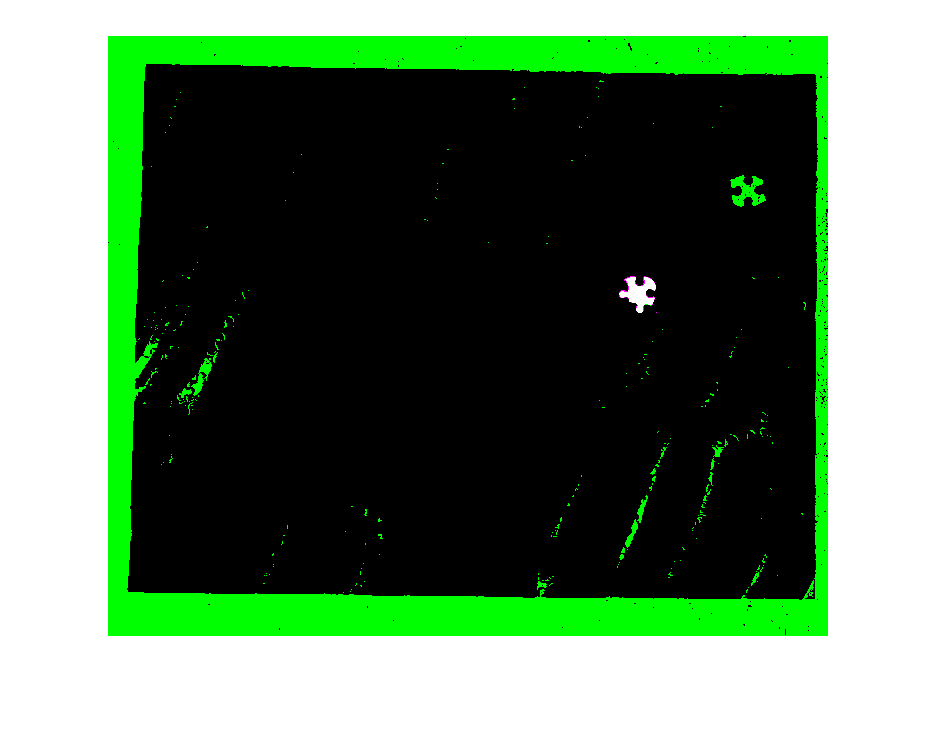

bi_main = main > 40;
bi_temp = temp > 100;

rotmat=[cos(pi/4) sin(pi/4);-sin(pi/4) cos(pi/4)];

rotimg=bi_temp;
oldpix=zeros(2,1);
newpix=zeros(2,1);
% nearest neighbor interpolation
shift=zeros(2,1);
shift(1,1)= size(bi_temp,1)/2;
shift(2,1)= size(bi_temp,2)/2;
rho=0;
rotations = zeros(size(bi_temp,1),size(bi_temp,2),8);
rotations(:,:,1)=bi_temp;
for stops=2:8
    theta = (stops-1)*pi/4;
    rotmat=[cos(theta) sin(theta);-sin(theta) cos(theta)];
    for i=1:size(bi_temp,1)
        for j=1:size(bi_temp,1)
            newpix(1,1)=i;
            newpix(2,1)=j;
            oldpix=round(rotmat*(newpix-shift)+shift);
            if (oldpix(1,1) > 0) & (oldpix(1,1) < size(bi_temp,1)) & (oldpix(2,1) > 0) & (oldpix(2,1) < size(bi_temp,2))
                rho=bi_temp(oldpix(1,1),oldpix(2,1));
            end
        rotimg(i,j)=rho;
        end
    end
    rotations(:,:,stops) = rotimg(1:size(bi_temp,1),1:size(bi_temp,2));
end
% figure
% colormap(gray)
% subplot(1, 2, 1)
% imagesc(bi_temp)
% title('Original')
% subplot(1,2,2)
% imagesc(rotations(:,:,4));
% title('Rotated')

blankscore=sum(~bi_temp(:));
pad_main=zeros(size(edge_main,1)+size(edge_temp,1),size(edge_main,2)+size(edge_temp,2));
pad_main(1:size(edge_main,1),1:size(edge_main,2))=bi_main;
accum2=zeros(size(bi_main,1),size(bi_main,2),8);
for i=1:size(edge_main,1)
    for j=1:size(edge_main,2)
        A=pad_main(i:i+size(edge_temp,1)-1,j:j+size(edge_temp,2)-1);
        B=rotations(:,:,1);
        C=abs(A-B); % least square
        C=C(:);
        accum2(i,j,1)=sum(C);
        if(accum2(i,j,1)>blankscore) % only rotate if raw original score 
            % higher than blank background
            for steps=2:8
                B = rotations(:,:,steps);
                C=abs(A-B);
                C=C(:);
                accum2(i,j,steps)=sum(C);
            end
        end
    end
end
accum2=accum2(1:size(bi_main,1),1:size(bi_main,2),:);
% figure
% imagesc(bi_main);

[i,j,k] = ind2sub(size(accum2),find(accum2 == max(max(max(accum2)))));
finalmain = zeros(size(main));
R = 0; 
G = 1;
B = 0;
finalmain = cat(3, ~bi_main * R, ~bi_main * G, ~bi_main * B);
finaltemp = zeros(size(finalmain));
finaltemp(i:i+size(bi_temp,1)-1,j:j+size(bi_temp,2)-1)=rotations(:,:,k);
final = imfuse(finalmain,finaltemp);
figure
imshow(final);

function new_angle = rotate(angle,stops)
    new_angle = (angle + pi/2 + (stops-1)*pi/4);
    new_angle = mod(new_angle,pi);
    new_angle = new_angle - pi/2;
end